BLI_st.name='BLI'; 
BLI_st.lat=38.9761;
BLI_st.lon=-120.103;
BLI_st.alt=2130;

BLI_rd=read_betsy('bliss_head',BLI_st.name);

datevec(BLI_rd.Time(1))

ans =         1996           7           2           0           0           0

datevec(BLI_rd.Time(end))

ans =         2006           4           1           0           0           0

prctile(BLI_rd.U_S,[5, 50, 95])

ans =    24.0132   50.5250   85.9622

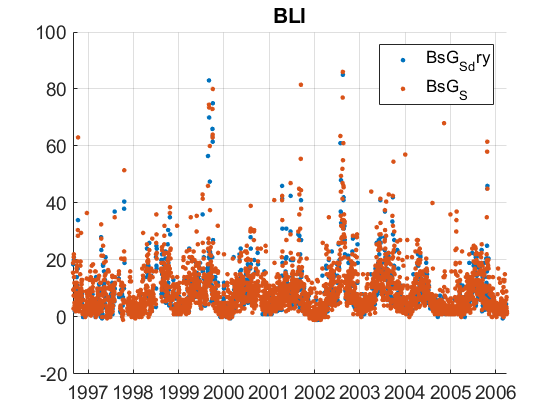

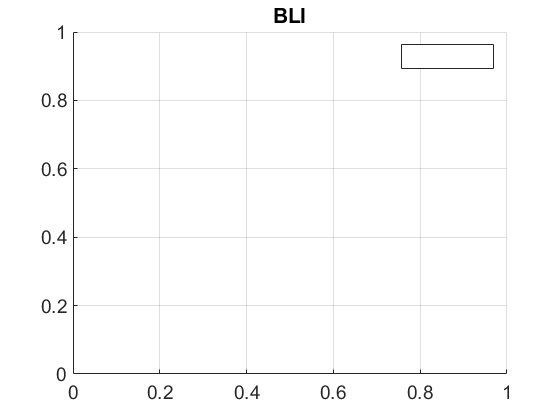

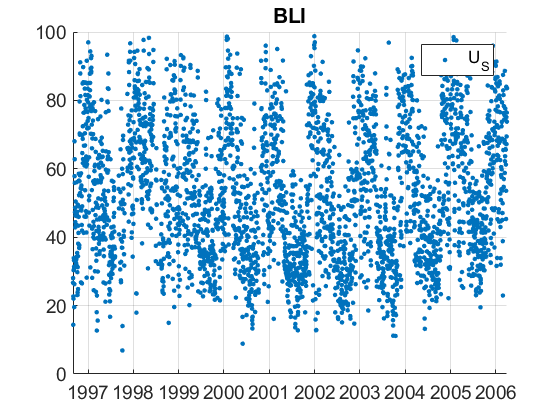

plotFigControl(BLI_rd,BLI_st.name);

% 1 size cut,
% sc: ok, clear seasonal cycle, max in summer, some negatives

lambdaSC=[450;550;700]*ones(1,4); lambdaAE3=[467;530;660]*ones(1,4); lambdaAE7=[370 470 520 590 660 880 950]; BLI_cal=compute_exp_SSA(BLI_rd,lambdaSC, lambdaAE3); plotFigControl_cal(BLI_cal, BLI_st.name);

%Questions:
%problems:
% station parameters: no question!

BLI_tr=BLI_rd;
BLI_tr.y=year(BLI_tr.Time);
%eneleve une valeur de 2019
BLI_tr=BLI_tr(1:end-1,:);
% begin at the beginning of a year: 1997
%end year: 2006
P=timerange('1997-01-01','2006-01-01');
BLI_tr=BLI_tr(P,:);

%see outliers
names=fieldnames(BLI_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    BLI_tr.(N{i})=[];
end


%not long enough for trend